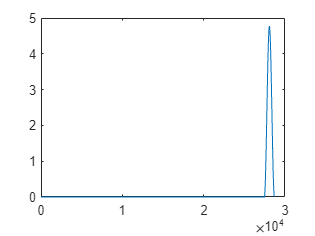

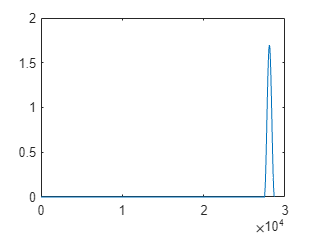

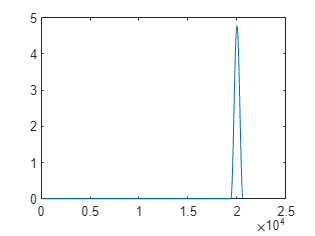

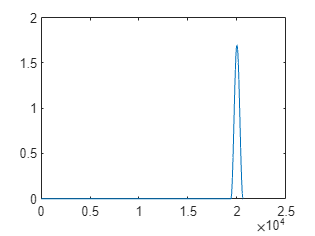

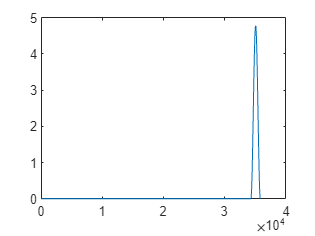

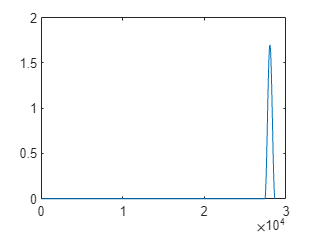

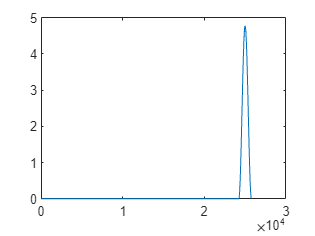

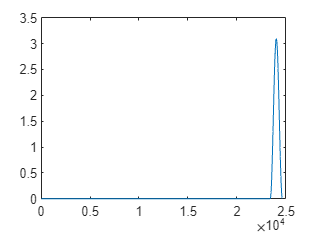

% Clap and Fling kinematics derived based on Sun & Yu (2006)
clc;
    
% Kinematic parameters (SI units)

org_data=readtable("AverageLift.xlsx","ReadVariableNames",0);
org_data=table2array(org_data);

org_data1=readtable("Wmax1.xlsx","ReadVariableNames",0);
org_data1=table2array(org_data1);
for l=[1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,26,27,28,29,30,31,32,33,34,35,36,37,38,39,40,41,43,44,45,46,47,48,49,50,51]
    temp_data=readtable("DragForceFiles\DragCalculated_"+string(l)+".dat","ReadVariableNames",0);
    temp_data=table2array(temp_data);
    
    
    zeta = org_data(l,2)/100; 
    if (l==16)
        zeta=(0.183996);
    end                             % Percentage overlap (1 means 100%)
    phi0 = 140*pi/180;                   % stroke amplitude (rad)
    N = 200;                            % flapping frequency (Hz)
    R = 2.161e-3;                         % Wing span (m)
    r2 = 1.22e-3;                        % radius of seond moment of wing area (mm) 
    c = 7.7e-4;                         % Wing chord (m)
    U = 2*phi0*N*r2;                     % Reference or maximum tip velocity (m/s)
    % U = 2*phi0*N*R;
    alpha_m = org_data(l,3)*pi/180;                % angle of attack during upstroke/downstroke (rad)
    thita_f_max = (90*pi/180-alpha_m);            % Maximum fling angle (rad)
    alpha_max = 2*thita_f_max;             % change in angle during flip (rad)
    thita_c_max = thita_f_max;            % Maximum clap angle (rad)
    W_max = 1-cos(org_data1(l)*pi/180);         % Upward movement of wing after clap (dimensionless)
    d = 0.0675*c;                         % Separation from the boundary  
    c_lb = 66.666;                          % Wing chord (lattice units)
    
    Re = org_data(l,1);                            % Reynolds Number
    U_lb = 0.025;
    
    if (l==5 || l==7 ||l==38)
        U_lb=0.02;
    end
    % Lattice Boltzmann conversion constants
    
    C_l = c/c_lb;              % m
    C_t = U_lb*C_l/U;          % sec
    %U_lb = U*C_t/C_l;                        % Reference or maximum tip velocity (lattice units)
    Time_period = 1/(N*C_t);
    % T = fix(Time_period);      % lattice time duration
    tau_lb = U_lb*c_lb*3/Re + 0.5;      % Relaxation Time
    
    % Original centre of mass
    fling_c = 0.65e-3;
    clap_c = c-fling_c;
    flip_c = 2.5216e-4;
    % downstroke_R = 0.8233e-3;
    % upstroke_R = downstroke_R;
    
    
    % Dimensionless time durations
    
    tau_c = (1/N)/(c/U);                % dimensionless duration of a stroke
    tau_0 = 0;                          % flapping start time
    
    del_tau_f = 0.11*tau_c;             % dimensionless duration of fling
    del_tau_r = 0.17*tau_c;             % dimensionless duration of flip
    del_tau_cl = 0.11*tau_c;            % dimensionless duration of clap
    del_tau_up = 0.06*tau_c;            % dimensinless duration of upward motion 
    del_tau_s = 0.47*tau_c;             % dimensionless duration of translation
    
    tau_dn = tau_0+(1-zeta)*del_tau_f;                      % downstroke start time
    tau_r = tau_dn+del_tau_s-0.5*zeta*del_tau_r;                      % flip start time
    tau_up = tau_r + del_tau_r - 0.5*zeta*del_tau_r;  % upstroke start time
    tau_cl = tau_up+del_tau_s-zeta*del_tau_cl;                % clap start time
    
    % Dimensionless constants
    
    thita_0_dot_plus = thita_f_max/(0.5*del_tau_f);      
    alpha_0_dot_plus = alpha_max/(0.5*del_tau_r);
    thita_1_dot_plus = thita_c_max/(0.5*del_tau_cl);  
    phi_0_dot_plus = phi0/(0.5*del_tau_s);
    W_0_dot_plus = W_max/(0.5*del_tau_up);
    
    T = fix((tau_cl+del_tau_cl+del_tau_up)*Time_period/tau_c);
    
    
    tau = linspace(0,tau_cl+del_tau_cl+del_tau_up,T);
    n = size(tau,2);
    Time = 1:n;
    
    thita_double_dot = zeros(n,1);
    thita_dot = zeros(n,1);
    thita = zeros(n,1);
    
    phi_double_dot = zeros(n,1);
    phi_dot = zeros(n,1);
    phi = zeros(n,1);
    
    
    % alpha_dot_plus = zeros(n,1);
    % 
    % thita_c_dot_plus = zeros(n,1);
    
    W_dot_plus = zeros(n,1);
    W = zeros(n,1);
    
    % omega_r = zeros(n,3);                      % angular velocity vector
    % omega_l = zeros(n,3);
    
    % Vel_r = zeros(n,3);                      % Translational velocity of COM
    % Vel_l = zeros(n,3);
    % Vel_mag = zeros(n);
    t = zeros(n,1);
    % Tip_Vel_r = zeros(n,3);                 % Translational velocity of Tip
    % LTip_Vel_r = zeros(n,3);                % Leading edge velocity
    % TTip_Vel_r = zeros(n,3);                % Trailing edge velocity
    % Root_Vel_r = zeros(n,3);                % Root velocity
    % Tip_Vel_mag = zeros(n,1);
    % LeadingEdge_Vel_r = zeros(n,1);
    % TrailingEdge_Vel_r = zeros(n,1);
    
    %%%%%     thita is alpha here %%%%
    
    % angular velocities and displacements
    for i=1:n
        
    if tau(i)>=tau_0 && tau(i)<=tau_0+del_tau_f   % fling
             
             thita_double_dot(i) = thita_0_dot_plus*pi*sin(2*pi*(tau(i)-tau_0)/del_tau_f)/del_tau_f;
             thita_dot(i) = 0.5*thita_0_dot_plus*(1-cos(2*pi*(tau(i)-tau_0)/del_tau_f));
             thita(i) = 0.5*thita_0_dot_plus*(tau(i)-tau_0-(sin(2*pi*(tau(i)-tau_0)/del_tau_f))/(2*pi/del_tau_f));           
    %          omega_r(i,1) = thita_f_dot_plus(i)*U/c*C_t;
    %          Vel_r(i,3) = Vel_r(i,3) + omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %          Vel_r(i,2) = Vel_r(i,2) - omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %          Tip_Vel_r(i,3) = Tip_Vel_r(i,3) + omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %          Tip_Vel_r(i,2) = Tip_Vel_r(i,2) - omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %          Root_Vel_r(i,3) = Root_Vel_r(i,3) + omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %          Root_Vel_r(i,2) = Root_Vel_r(i,2) - omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %          LTip_Vel_r(i,3) = LTip_Vel_r(i,3) + omega_r(i,1)*2*(fling_c)*cos(thita_r(i))/C_l;
    %          LTip_Vel_r(i,2) = LTip_Vel_r(i,2) - omega_r(i,1)*2*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %          TTip_Vel_r(i,3) = TTip_Vel_r(i,3);
    %          TTip_Vel_r(i,2) = TTip_Vel_r(i,2);
             
    end
     
    if tau(i)>tau_0+del_tau_f && tau(i)<tau_r
             
        thita(i) = thita_f_max;
           
    end   
     
     if tau(i)>=tau_dn && tau(i)<=tau_dn+del_tau_s      % downstroke
            phi_double_dot(i) = -phi_0_dot_plus*pi*sin(2*pi*(tau(i)-tau_dn)/del_tau_s)/del_tau_s;
            phi_dot(i) = -0.5*phi_0_dot_plus*(1-cos(2*pi*(tau(i)-tau_dn)/del_tau_s));
            phi(i) = -0.5*phi_0_dot_plus*(tau(i)-tau_dn-(sin(2*pi*(tau(i)-tau_dn)/del_tau_s))/(2*pi/del_tau_s));
    %         omega_r(i,2) = phi_dot_plus(i)*U/c*C_t;
    %         Vel_r(i,3) = Vel_r(i,3) - omega_r(i,2)*(R/2)*cos(phi_r(i))/C_l;
    %         Vel_r(i,1) = Vel_r(i,1) - omega_r(i,2)*(R/2)*sin(phi_r(i))/C_l;
    % 
    %         Root_Vel_r(i,3) = Root_Vel_r(i,3);
    %         Root_Vel_r(i,1) = Root_Vel_r(i,1);
    % 
    %         LTip_Vel_r(i,3) = LTip_Vel_r(i,3) - omega_r(i,2)*(R/2)*cos(phi_r(i))/C_l;
    %         LTip_Vel_r(i,1) = LTip_Vel_r(i,1) - omega_r(i,2)*(R/2)*sin(phi_r(i))/C_l;
    % 
    %         TTip_Vel_r(i,3) = TTip_Vel_r(i,3) - omega_r(i,2)*(R/2)*cos(phi_r(i))/C_l;
    %         TTip_Vel_r(i,1) = TTip_Vel_r(i,1) - omega_r(i,2)*(R/2)*sin(phi_r(i))/C_l;
    % 
    %         Tip_Vel_r(i,3) = Tip_Vel_r(i,3) - omega_r(i,2)*R*cos(phi_r(i))/C_l;
    %         Tip_Vel_r(i,1) = Tip_Vel_r(i,1) - omega_r(i,2)*R*sin(phi_r(i))/C_l;
     end
    
     if tau(i)>=tau_r && tau(i)<=tau_r+del_tau_r        % flip
            thita_double_dot(i) = alpha_0_dot_plus*pi*sin(2*pi*(tau(i)-tau_r)/del_tau_r)/del_tau_r;
            thita_dot(i) = -0.5*alpha_0_dot_plus*(1-cos(2*pi*(tau(i)-tau_r)/del_tau_r)); 
            thita(i) = thita_f_max - 0.5*alpha_0_dot_plus*(tau(i)-tau_r-(sin(2*pi*(tau(i)-tau_r)/del_tau_r))/(2*pi/del_tau_r));
    %         omega_r(i,1) = alpha_dot_plus(i)*U/c*C_t;
    %         phi_r(i) = phi0;
            
             %Vel_r(i,1) = Vel_r(i,1) + omega_r(i,1)*(flip_c)*cos(thita_r(i))/C_l;
             %Vel_r(i,2) = Vel_r(i,2) + omega_r(i,1)*(flip_c)*sin(thita_r(i))/C_l;
             
    %          Vel_r(i,1) = Vel_r(i,1); % + omega_r(i,1)*(flip_c)*cos(thita_r(i))/C_l;
    %          Vel_r(i,2) = Vel_r(i,2); % + omega_r(i,1)*(flip_c)*sin(thita_r(i))/C_l;
    %          
    %          Tip_Vel_r(i,3) = Tip_Vel_r(i,3);
    %          Tip_Vel_r(i,2) = Tip_Vel_r(i,2);
    % 
    %          Root_Vel_r(i,3) = Root_Vel_r(i,3);
    %          Root_Vel_r(i,2) = Root_Vel_r(i,2);
    % 
    %          LTip_Vel_r(i,3) = LTip_Vel_r(i,3) + omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %          LTip_Vel_r(i,2) = LTip_Vel_r(i,2) - omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %          TTip_Vel_r(i,3) = TTip_Vel_r(i,3) - omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %          TTip_Vel_r(i,2) = TTip_Vel_r(i,2) + omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    
            
     end
    
     if tau(i)>=tau_dn+del_tau_s && tau(i)<=tau_up
            phi(i) = -phi0;
     end
            
     if tau(i)>tau_up && tau(i)<=tau_up+del_tau_s       % upstroke
            phi_double_dot(i) = phi_0_dot_plus*pi*sin(2*pi*(tau(i)-tau_up)/del_tau_s)/del_tau_s;
            phi_dot(i) = 0.5*phi_0_dot_plus*(1-cos(2*pi*(tau(i)-tau_up)/del_tau_s));
            phi(i) = -phi0+0.5*phi_0_dot_plus*(tau(i)-tau_up-(sin(2*pi*(tau(i)-tau_up)/del_tau_s))/(2*pi/del_tau_s));
    %         omega_r(i,2) = phi_dot_plus(i)*U/c*C_t;  
    %         Vel_r(i,3) = Vel_r(i,3) - omega_r(i,2)*(R/2)*cos(phi_r(i))/C_l;
    %         Vel_r(i,1) = Vel_r(i,1) - omega_r(i,2)*(R/2)*sin(phi_r(i))/C_l;
    % 
    %         Root_Vel_r(i,3) = Root_Vel_r(i,3);
    %         Root_Vel_r(i,1) = Root_Vel_r(i,1);
    % 
    %         LTip_Vel_r(i,3) = LTip_Vel_r(i,3) - omega_r(i,2)*(R/2)*cos(phi_r(i))/C_l;
    %         LTip_Vel_r(i,1) = LTip_Vel_r(i,1) - omega_r(i,2)*(R/2)*sin(phi_r(i))/C_l;
    % 
    %         TTip_Vel_r(i,3) = TTip_Vel_r(i,3) - omega_r(i,2)*(R/2)*cos(phi_r(i))/C_l;
    %         TTip_Vel_r(i,1) = TTip_Vel_r(i,1) - omega_r(i,2)*(R/2)*sin(phi_r(i))/C_l;
    % 
    %         Tip_Vel_r(i,3) = Tip_Vel_r(i,3) - omega_r(i,2)*R*cos(phi_r(i))/C_l;
    %         Tip_Vel_r(i,1) = Tip_Vel_r(i,1) - omega_r(i,2)*R*sin(phi_r(i))/C_l;
    
     end
     
     if tau(i)>tau_r+del_tau_r && tau(i)<tau_cl    
         thita(i) = -thita_f_max; 
     end
     
     if tau(i)>=tau_cl && tau(i)<=tau_cl+del_tau_cl    % clap      
            thita_double_dot(i) = thita_1_dot_plus*pi*sin(2*pi*(tau(i)-tau_cl)/del_tau_cl)/del_tau_cl;
            thita_dot(i) = 0.5*thita_1_dot_plus*(1-cos(2*pi*(tau(i)-tau_cl)/del_tau_cl));
            thita(i) = -thita_f_max+0.5*thita_1_dot_plus*(tau(i)-tau_cl-(sin(2*pi*(tau(i)-tau_cl)/del_tau_cl))/(2*pi/del_tau_cl));
    %         omega_r(i,1) = thita_c_dot_plus(i)*U/c*C_t;
    %         Vel_r(i,3) = Vel_r(i,3) - omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %         Vel_r(i,2) = Vel_r(i,2) + omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %         LTip_Vel_r(i,3) = LTip_Vel_r(i,3);
    %         LTip_Vel_r(i,2) = LTip_Vel_r(i,2);
    % 
    %         Root_Vel_r(i,3) = Root_Vel_r(i,3) - omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %         Root_Vel_r(i,2) = Root_Vel_r(i,2) + omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %         Tip_Vel_r(i,3) = Tip_Vel_r(i,3) - omega_r(i,1)*(fling_c)*cos(thita_r(i))/C_l;
    %         Tip_Vel_r(i,2) = Tip_Vel_r(i,2) + omega_r(i,1)*(fling_c)*sin(thita_r(i))/C_l;
    % 
    %         TTip_Vel_r(i,3) = TTip_Vel_r(i,3) - omega_r(i,1)*(2*fling_c)*cos(thita_r(i))/C_l;
    %         TTip_Vel_r(i,2) = TTip_Vel_r(i,2) + omega_r(i,1)*(2*fling_c)*sin(thita_r(i))/C_l;
            
     end
    
     if tau(i)>=tau_cl+del_tau_cl && tau(i)<=tau_cl+del_tau_cl+del_tau_up  % vertical movement
            W_dot_plus(i) = 0.5*W_0_dot_plus*(1-cos(2*pi*(tau(i)-tau_cl-del_tau_cl)/del_tau_up));
            W(i) = 0.5*W_0_dot_plus*U*(tau(i)-(sin(2*pi*(tau(i)-tau_cl-del_tau_cl)/del_tau_up))/(2*pi/del_tau_up));     
    %         Vel_r(i,2) = Vel_r(i,2) + W_dot_plus(i)*U*C_t/C_l; 
    %         LTip_Vel_r(i,2) = LTip_Vel_r(i,2) + W_dot_plus(i)*U*C_t/C_l; 
    %         Root_Vel_r(i,2) = Root_Vel_r(i,2) + W_dot_plus(i)*U*C_t/C_l; 
    %         TTip_Vel_r(i,2) = TTip_Vel_r(i,2) + W_dot_plus(i)*U*C_t/C_l; 
     end 
    
    
        t(i)=tau(i)/tau_c;
    %     Vel_mag(i) = (Vel_r(i,1)*Vel_r(i,1)+Vel_r(i,2)*Vel_r(i,2)+Vel_r(i,3)*Vel_r(i,3))^0.5;
    %     Tip_Vel_mag(i) = (Tip_Vel_r(i,1)*Tip_Vel_r(i,1)+Tip_Vel_r(i,2)*Tip_Vel_r(i,2)+Tip_Vel_r(i,3)*Tip_Vel_r(i,3))^0.5;
    %     LeadingEdge_Vel_r(i) = (LTip_Vel_r(i,1)*LTip_Vel_r(i,1) + LTip_Vel_r(i,2)*LTip_Vel_r(i,2) + LTip_Vel_r(i,3)*LTip_Vel_r(i,3))^0.5;
    %     TrailingEdge_Vel_r(i) = (TTip_Vel_r(i,1)*TTip_Vel_r(i,1) + TTip_Vel_r(i,2)*TTip_Vel_r(i,2) + TTip_Vel_r(i,3)*TTip_Vel_r(i,3))^0.5;
    end
    
    % thita_l = -thita_r;
    % phi_l = -phi_r;
    % Vel_l(:,1) = Vel_r(:,1);
    % Vel_l(:,2) = Vel_r(:,2);
    % Vel_l(:,3) = -Vel_r(:,3);
    % 
    % omega_l = -omega_r;
    % 
    % X_plus = zeros(n,3);            % dimensionless displacement/position vector of the right wing COM 
    % Root_plus = zeros(n,3);
    % Leading_plus = zeros(n,3);
    % Trailing_plus = zeros(n,3);
    % X_neg = zeros(n,3);             % dimensionless displacement/position vector of the left wing COM 
    % 
    % X_r = zeros(n,3);                 % diaplacement/position vector of the wing COM
    % X_l = zeros(n,3);                 % diaplacement/position vector of the wing COM
    
    % X_r(1,1) = 5*c/C_l+c/(2*C_l); X_r(1,2) = 5*c/C_l+c/(4*C_l); X_r(1,3) =(d)/C_l;   % initial position of the COM of right wing 
    % Root_r(1,1) = 5*c/C_l+c/(2*C_l)-117.26; Root_r(1,2) = 5*c/C_l+c/(4*C_l); Root_r(1,3) = (d)/C_l;
    % Leading_r(1,1) = 5*c/C_l+c/(2*C_l); Leading_r(1,2) = 5*c/C_l+c/(4*C_l)+fling_c/C_l; Leading_r(1,3) = (d)/C_l;
    % Trailing_r(1,1) = 5*c/C_l+c/(2*C_l); Trailing_r(1,2) = 5*c/C_l+c/(4*C_l)-fling_c/C_l; Trailing_r(1,3) = (d)/C_l;
    % X_l(1,1) =  3*c/C_l+c/(2*C_l); X_l(1,2) = 3*c/C_l+c/(4*C_l); X_l(1,3) = (3*c-0.5*d)/C_l;   % initial position of the COM of left wing 
    
    % X_plus = cumtrapz(tau,Vel_r*C_l/(U*C_t));   % X/c
    % Root_plus = cumtrapz(tau,Root_Vel_r*C_l/(U*C_t));   % X/c
    % Leading_plus = cumtrapz(tau,LTip_Vel_r*C_l/(U*C_t));   % X/c
    % Trailing_plus = cumtrapz(tau,TTip_Vel_r*C_l/(U*C_t));   % X/c
    % X_neg = cumtrapz(tau,Vel_l*C_l/(U*C_t));
    
    % X_r = X_r(1,:) + X_plus*c/C_l;
    % Root_r = Root_r(1,:) + Root_plus*c/C_l;
    % Leading_r = Leading_r(1,:) + Leading_plus*c/C_l;
    % Trailing_r = Trailing_r(1,:) + Trailing_plus*c/C_l;
    % X_l = X_l(1,:) + X_neg*c/C_l;
    
    % figure(1);
    % plot(tau/tau_c,thita_f_dot_plus,tau/tau_c,thita_c_dot_plus,'--',tau/tau_c,alpha_dot_plus,'.',tau/tau_c,phi_dot_plus,'-.',tau/tau_c,W_dot_plus,':')
    % hLeg=legend('$$\dot{\theta_f^+}$$','$$\dot{\theta_c^+}$$','$$\dot{\alpha^+}$$','$$\dot{\phi^+}$$','$$\dot{W^+}$$');
    % set(hLeg,'Interpreter','latex');
    % % 
    %  figure (2);  % angular displacements
    %  
    %  plot(tau/tau_c,thita_r*180/pi,tau/tau_c,phi_r*180/pi,'-.');
    %  title('Right wing');
    %  hLeg=legend('$$\theta$$','$$\phi$$');
    %  set(hLeg,'Interpreter', 'latex');
    %  
    %  figure(3);   % COM dimensional velocity
    %  subplot(2,1,1);
    %  plot(tau/tau_c,Vel_r(:,1),tau/tau_c,Vel_r(:,2),'-',tau/tau_c,Vel_r(:,3),'.');
    %  legend('V_x','V_y','V_z');
    %  title('Right wing');
    %  
    %  
    %  figure(4);   % COM angular velocity
    %  subplot(2,1,1);
    %  plot(tau/tau_c,omega_r(:,1),tau/tau_c,omega_r(:,2),'-',tau/tau_c,omega_r(:,3),'.');
    %  legend('w_x','w_y','w_z');
    %  title('Right wing');
    %  
    %  figure(5);  % dimensionless positions
    %  subplot(2,1,1);
    %  plot(tau/tau_c,X_plus(:,1),tau/tau_c,X_plus(:,2),'-',tau/tau_c,X_plus(:,3),'.');
    %  legend('X^+','Y^+','Z^+');
    %  title('Right wing');
    %  
    % 
    %  figure(6); % dimensional positions
    %  subplot(3,1,1); plot(tau/tau_c,X_r(:,1)); title('X_r');
    %  subplot(3,1,2); plot(tau/tau_c,X_r(:,2)); title('Y_r');
    %  subplot(3,1,3); plot(tau/tau_c,X_r(:,3)); title('Z_r'); 
    % 
    % figure(7);
    % plot(tau/tau_c,Vel_mag); title('Velocity Magnitude');
    % 
    %  figure(8)
    % %  plot(tau/tau_c,X_r(:,1),tau/tau_c,X_r(:,2),'-',tau/tau_c,X_r(:,3),'.');
    %  plot(tau/tau_c,X_r(:,3));
    %  title('Z_cm');
    %  xlabel('Dimensionless Time');
    %  ylabel('Z');
    % 
    % figure(9);
    % plot(tau/tau_c,Tip_Vel_mag,tau/tau_c,TrailingEdge_Vel_r,'--',tau/tau_c,LeadingEdge_Vel_r,'.')
    % hLeg=legend('Tip Velocity','Trailing Edge Velocity','Leading Edge Velocity');
    % set(hLeg,'Interpreter','latex');
    % 
    % figure(10); % dimensional positions
    %  subplot(3,1,1); plot(tau/tau_c,Root_r(:,1)); title('Root_x');
    %  subplot(3,1,2); plot(tau/tau_c,Root_r(:,2)); title('Root_y');
    %  subplot(3,1,3); plot(tau/tau_c,Root_r(:,3)); title('Root_z');
    % 
    %  figure(11); % dimensional positions
    %  subplot(3,1,1); plot(tau/tau_c,Leading_r(:,1)); title('Leading_x');
    %  subplot(3,1,2); plot(tau/tau_c,Leading_r(:,2)); title('Leading_y');
    %  subplot(3,1,3); plot(tau/tau_c,Leading_r(:,3)); title('Leading_z');
    % 
    %  figure(12); % dimensional positions
    %  subplot(3,1,1); plot(tau/tau_c,Trailing_r(:,1)); title('Trailing_x');
    %  subplot(3,1,2); plot(tau/tau_c,Trailing_r(:,2)); title('Trailing_y');
    %  subplot(3,1,3); plot(tau/tau_c,Trailing_r(:,3)); title('Trailing_z');
    
    % A = [Time' X_r(:,1) X_r(:,2) X_r(:,3) thita_r phi_r Root_r(:,1) Root_r(:,2) Root_r(:,3) Leading_r(:,1) Leading_r(:,2) Leading_r(:,3) Trailing_r(:,1) Trailing_r(:,2) Trailing_r(:,3) Vel_r(:,1) Vel_r(:,2) Vel_r(:,3) omega_r(:,1) omega_r(:,2)];
    % fileID = fopen('Clap_fling.dat','w');
    % fprintf(fileID,'%d\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\t%.8f\n',A');
    % fclose(fileID);
      
%      hold off;
%      figure(l)
%      plot(tau/tau_c,thita,tau/tau_c,thita_dot,'--',tau/tau_c,thita_double_dot,'.',tau/tau_c,phi,'-.',tau/tau_c,phi_dot,':',tau/tau_c,phi_double_dot,':')
%      hLeg=legend('$$\dot{\theta^+}$$','$$\dot{\theta_dot^+}$$','$$\dot{\thita_double_dot^+}$$','$$\dot{\phi^+}$$','$$\dot{phi_dot}$$','$$\dot{phi_double_dot}$$');
%      set(hLeg,'Interpreter','latex');
       
     lift_values=temp_data(:,2);
     figure
     plot(W_dot_plus);

     T = table(thita,thita_dot,thita_double_dot,phi,phi_dot,phi_double_dot,W_dot_plus,lift_values,'VariableNames', {'thita','thita_dot','thita_double_dot','phi','phi_dot','phi_double_dot','W_dot_plus','lift'});
     writetable(T, 'Feature_Data_Case\Feature_Data_Case_'+string(l)+'.dat', 'WriteVariableNames', true)
end